clear

addpath("matlab_functions\")

#### Add defect to plate

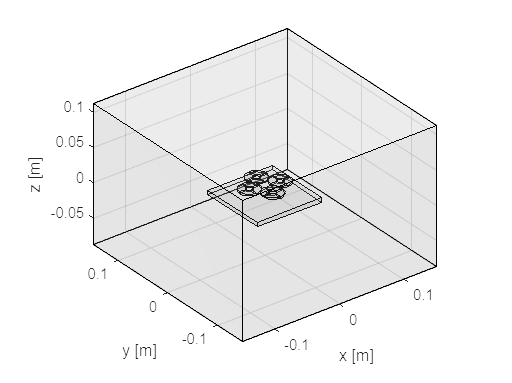

[Plate, Coil, Sensor, Model] = myModel;
freqs = [900 225 100 55]; % (Hz)
mesh_size = 2; % 1:finest 9:coarsest

global defects
defects = {};

% ComsolModel('AddRectangularDefect', Model, 5e-3, 0, 4e-3, 4e-3, 0, -3e-3)
ComsolModel('AddCircularDefect',    Model, 5e-3, 0, 4e-3,       0, -3e-3)

figure
ComsolModel('PlotGeometry', Model)

#### Compute fields

B_data = zeros(length(freqs), size(Sensor.positions,2));

for i = 1:length(freqs)
    ComsolModel('SolveCoil', Model, Coil, freqs(i), mesh_size);
    
    [x,y,z] = ndgrid( ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        -2e-3 );
    r = [reshape(x,1,[]); reshape(y,1,[]); reshape(z,1,[])];
    J = ComsolModel('InterpField', Model, 'J', r);
    
    figure
    imagesc([min(x) max(x)],[min(y) max(y)], ...
            reshape(vecnorm(J),500,500).')
    colorbar
    axis square xy
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(sprintf('$J$ norm (A/m$^2$) @ %d Hz',freqs(i)), 'Interpreter','latex')

    B = ComsolModel('InterpField', Model, 'B', Sensor.positions);
    B_data(i,:) = dot(B, Sensor.axes);
end

clear i x y z r J B mesh_size

#### Export sensor data

fname = sprintf('data/B_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %g Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(B_data(i,:)));
end

fclose(fid);

clear fname fid i